clc
clear
close all
set(0,'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);

rng(1)
% You will implement regularized logistic regression to predict whether
% microchips from a fabrication plant passes quality assurance (QA).
% During QA, each microchip goes through various tests to ensure it is
% functioning correctly. Suppose you are the product manager of the
% factory and you have the test results for some microchips on two different
% tests. From these two tests, you would like to determine whether the
% microchips should be accepted or rejected. To help you make the decision,
% you have a dataset of test results on past microchips,
% from which you can build a logistic regression model.

## Load Data

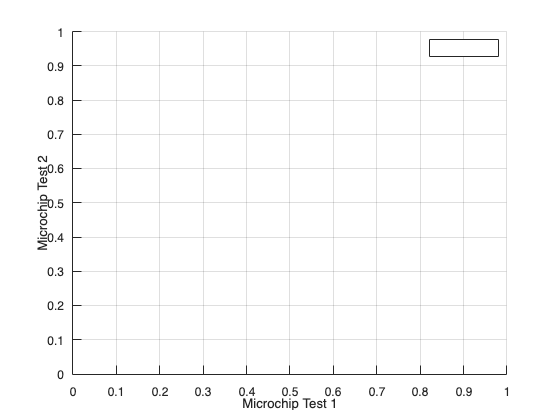

data = load('Data/ex2data2.txt');
X = data(:, [1, 2]); % regressors (features) matrix
y = data(:, 3); % labels


plotData(X, y);
grid on;
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
legend('y = 1', 'y = 0')


% The above figure shows that our dataset cannot be separated into positive
% and negative examples by a straight-line through the plot.
% Therefore, a straight-forward application of logistic regression
% will not perform well on this dataset since logistic regression will only
% be able to find a linear decision boundary.

## Polynomial features

% Add Polynomial Features

% Note that mapFeature also adds a column of ones for us, so the intercept
% term is handled
degree = 6; % degree of polynomial features
X_map = mapFeature(X(:,1), X(:,2), degree); % create polynomial features

% Get train and test data
cv = cvpartition( size(X,1), 'HoldOut', 0.3); % partition data 70% train - 30% validation
idx = cv.test; % get index of validation data

X_train = X_map(~idx, :); % train data
X_validation = X_map(idx, :); % validation data
y_train = y(~idx, :); % train labels
y_validation = y(idx, :); % validation labels

##  Regularizied logistic regression 

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set regularization parameter lambda to 0 (you should vary this)
lambda = 0;

% Compute and display initial cost and gradient for regularized logistic
% regression
[cost, grad] = costFunctionReg(initial_theta, X_train, y_train, lambda);

fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147




% Set Optimization Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
    fminunc(@(t)(costFunctionReg(t, X_train, y_train, lambda)), initial_theta, options);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


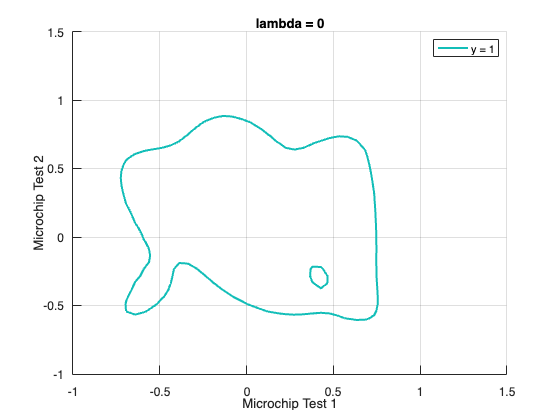


% Plot Boundary
plotDecisionBoundary(theta, X_train, y_train, degree);
hold on;
title(sprintf('lambda = %g', lambda))
xlabel('Microchip Test 1');
ylabel('Microchip Test 2');
grid on;
legend('y = 1', 'y = 0', 'Decision boundary')


% Get classification estimates
p_train = predict(theta, X_train); % classification on train data

p = 83×1 logical array
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1


p_validation = predict(theta, X_validation); % classification on validation data

p = 35×1 logical array
   1
   1
   1
   1
   1
   0
   0
   1
   1
   1



% Compute classification accuracy
fprintf('Train Accuracy: %f\n', mean(double(p_train == y_train)) * 100);

Train Accuracy: 91.566265


fprintf('Validation Accuracy: %f\n', mean(double(p_validation == y_validation)) * 100);

Validation Accuracy: 71.428571


## A simple validation procedure

degree_max = 10; % max polynomial degree for polynomial features
accuracy_train = zeros(degree_max, 1);
accuracy_validation = zeros(degree_max, 1);

for degree = 1 : 1 : degree_max  % degree of polynomial features
    
    X_map = mapFeature(X(:,1), X(:,2), degree); % map original features to polynomial features
    
    X_train = X_map(~idx, :); % train data
    X_validation = X_map(idx, :); % validation data
    
    
    % fit not regularized logistic regression model
    mdl = fitglm(X_train, y_train, 'Distribution', 'binomial');
    
    % Obtain probability estimates
    yhat_train_probs = predict(mdl, X_train); % estimates
    yhat_test_probs = predict(mdl, X_validation);
    
    % Threshold the estimated probabilities to obtain a classification result
    yhat_train_class = yhat_train_probs > 0.5;
    yhat_test_class = yhat_test_probs > 0.5;
    
    % Compute accuracy
    accuracy_train(degree) = mean(yhat_train_class == y_train);
    accuracy_validation(degree) = mean(yhat_test_class == y_validation);
    
end

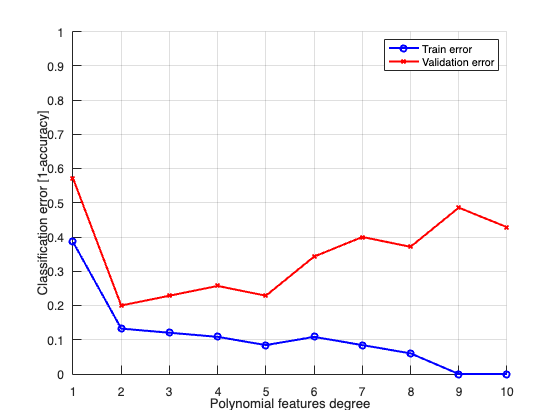


figure;
hold all
plot(1:degree_max, 1 - accuracy_train, 'bo-');
plot(1:degree_max, 1 - accuracy_validation, 'rx-');
grid on
xlim([1, degree_max]); ylim([0, 1]);
xlabel('Polynomial features degree');
ylabel('Classification error [1-accuracy]');
legend('Train error', 'Validation error')